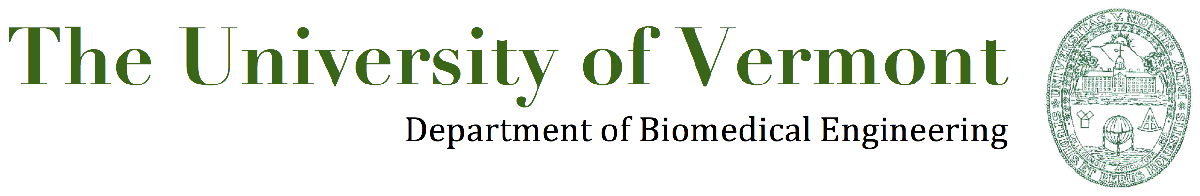

**Activity of Daily Living Analysis with Matlab**

Written by Ryan S. McGinnis - ryan.mcginnis@uvm.edu

**Background**

Talk with your lab partner about the following questions and make some notes in your lab document about what you discuss. You should have this discussion prior to completing the lab as outlined below.

1. Why might an investigator or clinician want to track acitivites of daily living?

2. How do you think the sensor data is used to determine activities of daily living?

3. How do you think the sensor data is used to determine posture?

**Loading Data and Basic Manipulation**

*Load Data*

dt = readtable('adl_subjects_data.csv');

Error using readtable (line 197)
Unable to open file 'adl_subjects_data.csv'.

4. List the variables and their types.

5. What does this dataset contain?

6. How many subjects does this dataset contain?

*Fix Variable types*

dt.Activity = categorical(dt.Activity);
dt.CoronalState = categorical(dt.CoronalState);
dt.SagittalState = categorical(dt.SagittalState);
dt.Subject = categorical(dt.Subject);

7. What categories are in each of the categorical variables? (hint: try the summary() command)

8. Do we have the same amount of data from each subject?

*Convert timestamp strings in dt.Ts to datetime objects*

dt.Ts = datetime(dt.Ts,'InputFormat','uuuu-MM-dd HH:mm:ssZ','TimeZone','America/New_York');

9. What did we change in dt.Ts with the last command?

*Recode some of the subject names and check result*

% Recode subjects that have two different subject names
dt.Subject(dt.Subject=='S0001V2')='S0001';
dt.Subject(dt.Subject=='S0027V2')='S0027';
dt.Subject(dt.Subject=='S0033V2')='S0033';
dt.Subject(dt.Subject=='S0047V2')='S0047';
dt.Subject(dt.Subject=='S0058V2')='S0058';
dt.Subject(dt.Subject=='S0065V2')='S0065';
dt.Subject(dt.Subject=='S0074V2')='S0074';

% Remove subjects who do not have at least 2 days worth of data
dt(dt.Subject=='S0002',:) = [];
dt(dt.Subject=='S0049TEST',:) = [];
dt(dt.Subject=='S0049TEST2',:) = [];

% Remove unnecessary categories and summarize subjects to check
dt.Subject = removecats(dt.Subject);
summary(dt.Subject);

*Visualize time series of categorical data for one subject*

% First isolate data from 1 subject 
dt1 = dt(dt.Subject=='S0050',:);

% Make sure the data for this subject is in chronological order
dt1 = sortrows(dt1,'Ts');

% Plot data from the subject
[g,gn,gl]=grp2idx(dt1.Activity);

figure; 
plot(dt1.Ts, g);
xtickangle(45);
yticks(1:length(gn));
yticklabels(gn);
ytickangle(45);
ylim([0,7]);
xlabel('Time'); ylabel('Activity');

Zoom into data from March 3rd and 4th to answer the following questions:

10. How often is an activity reported (i.e what is the sampling rate?)

11. When did the subject first put the device on?  When did they take the device off? Is there a period of time when they aren't wearing the device?

12. What does each vertical line represent?

13. At what time do you think the subject went to sleep on March 3rd/4th? Why?

*Visualize time series of continuous data for one subject*

% Plot data from the subject we isolated before
figure; 
plot(dt1.Ts, dt1.SagittalAngle);
ax = gca; ax.XTickLabelRotation = 45;
xlabel('Time'); ylabel('Sagittal Angle (deg)');

Zoom into data from March 3rd and 4th to answer the following questions:

14. What are the minimum and maximum sagittal posture angles?

15. At what times do these occur? 

16. What might the subject be doing during these periods? 

**Summarizing Time Series Data**

*Categorical data*

% Summarize activity data for one subject
summary(dt1.Activity)
% Examine the number of epochs spent within each activity by considering the histogram
figure; 
hist(dt1.Activity); 
xtickangle(45);
xlabel('Activity');
ylabel('Epoch Count');

17. How much more time did this subject spend sitting than lying or standing?

18. What percentage of time did this subject spend walking?

*Continuous data*

% Summarize sagittal plane posture data for one subject
summary(dt1);
% Examine the distribution of sagittal posture angles by considering the histogram
figure; 
hist(dt1.SagittalAngle);
xtickangle(45);
xlabel('Sagittal Angle (deg.)');
ylabel('Epoch Count');

19. What are the summary measures for the continuous SagittalAngle variable? 

20. Describe the sagittal angle distribution in words.

**Examining Data Across Subjects **

*Define new variables for the amount of time spent doing each activity*

% Initialize new table for holding our data
subjects = unique(dt.Subject);
zeropad = zeros(length(subjects),1);
dtsum = table(subjects,zeropad,zeropad,zeropad,zeropad,zeropad,zeropad,...
    'VariableNames',{'Subject','MoveLie','MoveWalk','MoveOther','RestSit','RestStand','RestLie'});
for sub_ind = 1:length(subjects)
    % Extract row for subject
    sub = subjects(sub_ind);
    row = dtsum(dtsum.Subject==sub, :); 
    
    % Extract time series data for subject
    dt_temp = dt(dt.Subject==sub,:);
    
    % Assign time that subject spent in each activity
    row.MoveWalk = sum(dt_temp.Activity=='MOVING:STANDING_MOVING:WALKING');
    row.MoveLie = sum(dt_temp.Activity=='MOVING:LYING_MOVING');
    row.MoveOther = sum(dt_temp.Activity=='MOVING:STANDING_MOVING:OTHER');
    row.RestSit = sum(dt_temp.Activity=='RESTING:SITTING');
    row.RestStand = sum(dt_temp.Activity=='RESTING:STANDING');
    row.RestLie = sum(dt_temp.Activity=='RESTING:LYING');
    
    % Insert row back into table
    dtsum(dtsum.Subject==sub, :) = row;
end

21. Are these variables continuous?

22. What is the mean time spent sitting across all of the subjects?

*Visualize time spent in each activity across subjects with a box plot*

figure;
boxplot(table2array(dtsum(:,2:end)));
xticklabels(dtsum.Properties.VariableNames(2:end))
ylabel('Epochs'); xlabel('Activity');

23. Label the components of the box plot (i.e. what are the red and blue lines? the red crosses? etc.)